%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                FMCW Radar Simulator               %
%      Multi-lane, Multi-vehicle Traffic Radar      %
%                                                   %
% Author: Lin Junyang                               %
% Email : linjy@163.com                             %
% Date  : 2021-1-16                                 %
%                                                   %
% All Rights Reserved.                              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% A simulatior of 1 TX antena and 4 RX antena FMCW radar.
% Simulation of close handwave movement: Left - Right

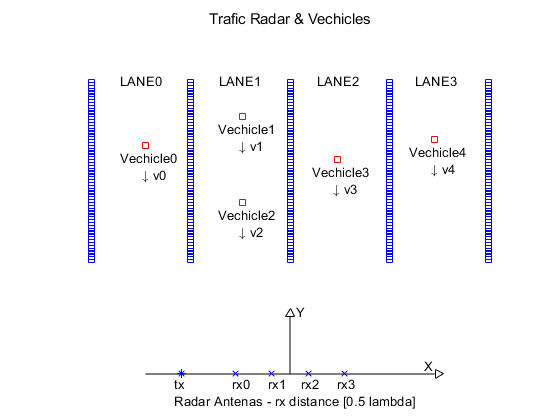

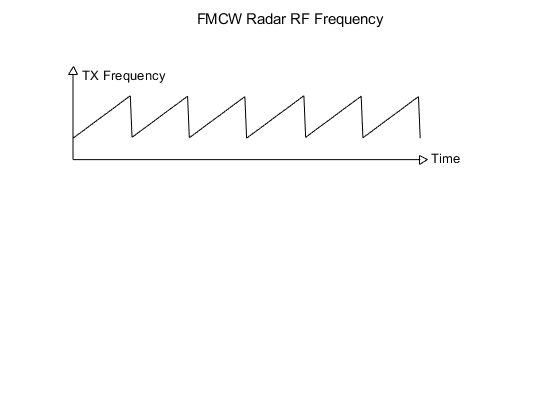

plot_scene

SimulationTime = 1.5;                   % simulation time seconds
SampleRate = 10e6;                      % 10MHz radar data sample rate
dt = 1/SampleRate;                      % data point interval
ChirpPeriod = 100e-6;                   % 1ms
ChirpNum = SimulationTime/ChirpPeriod;  % number of chirps
N = SimulationTime*SampleRate;          % data points for simulation
n = 1:N;                                % data points indexes
t = (n-1)*dt;                           % time

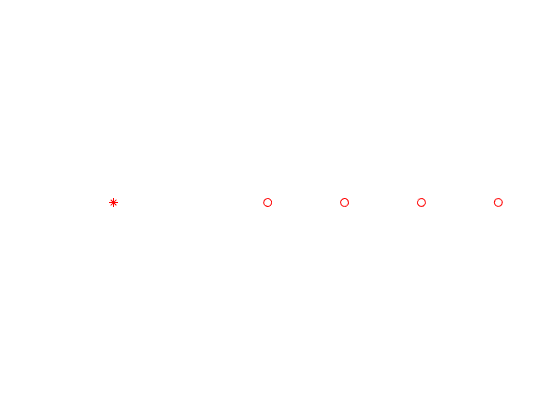

c = 3e8;                 % speed of light
B = 250e6;               % radar band width
S = B/ChirpPeriod;       % radar parameter, band slope
Dres = c/2/B;            % distance resolution
Lambda = 0.0124;         % radar parameter, 12mm lamda (24G)
Drx = Lambda/2;          % rx interval distance

tx0 = -3.5*Drx;          % tx position x
ty0 = 0;                 % tx position y
rx0 = -1.5*Drx;          % rx1 position x
ry0 = 0;                 % rx1 position y
rx1 = -0.5*Drx;          % rx2 position x
ry1 = 0;                 % rx2 position y
rx2 = 0.5*Drx;           % rx1 position x
ry2 = 0;                 % rx1 position y
rx3 = 1.5*Drx;           % rx2 position x
ry3 = 0;                 % rx2 position y

% figure;hold on;axis off
% plot(tx0,ty0,'r*')
% plot(rx0,ry0,'ro')
% plot(rx1,ry1,'ro')
% plot(rx2,ry2,'ro')
% plot(rx3,ry3,'ro')

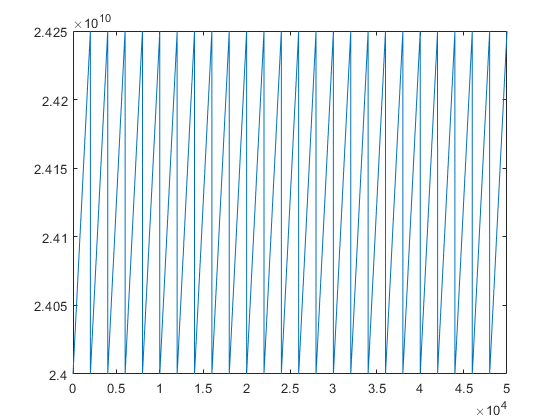

tx_f = 24.0e9 + mod(t,ChirpPeriod)*S;
% figure; title('tx_f');plot(tx_f(1:50000))

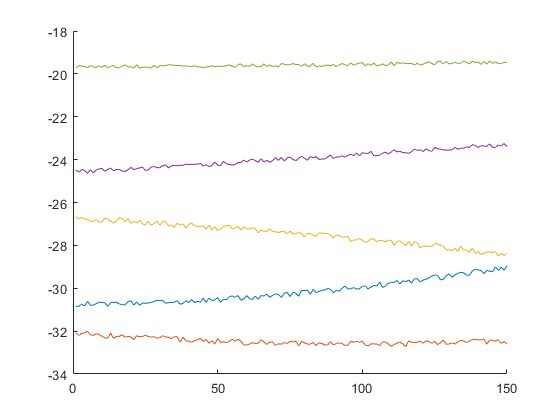

v0 = -17.8*(1+cos(0.8*t + 2*pi*rand())/10+rand(1,N)/100);
v1 = -19.5*(1+cos(0.6*t + 2*pi*rand())/10+rand(1,N)/100);
v2 = -19.1*(1+cos(0.5*t + 2*pi*rand())/10+rand(1,N)/100);
v3 = -13.2*(1+cos(0.4*t + 2*pi*rand())/10+rand(1,N)/100);
v4 = -11.8*(1+cos(0.3*t + 2*pi*rand())/10+rand(1,N)/100);

% figure; hold on; 
% plot(v0(1:100000:end))
% plot(v1(1:100000:end))
% plot(v2(1:100000:end))
% plot(v3(1:100000:end))
% plot(v4(1:100000:end))

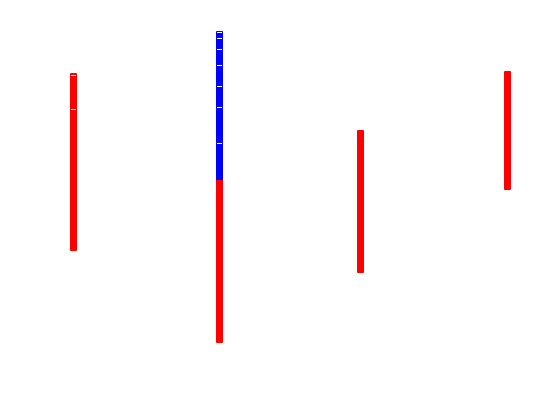

rcs0 = 0.1;
rcs1 = 0.12;
rcs2 = 0.11;
rcs3 = 0.88;
rcs4 = 0.93;

px0 = -4;
px1 = -1.3;
px2 = -1.3;
px3 = 1.3;
px4 = 4;

py0 = zeros(1,N);         % Vechile0 y postion
py1 = zeros(1,N);         % Vechile1 y postion
py2 = zeros(1,N);         % Vechile2 y postion
py3 = zeros(1,N);         % Vechile3 y postion
py4 = zeros(1,N);         % Vechile4 y postion

py0(1) = 108;
py1(1) = 119;
py2(1) = 80;
py3(1) = 93;
py4(1) = 108.5;
for k = 2:N
    py0(k) = py0(k-1) + v0(k-1)*dt;
    py1(k) = py1(k-1) + v1(k-1)*dt;
    py2(k) = py2(k-1) + v2(k-1)*dt;
    py3(k) = py3(k-1) + v3(k-1)*dt;
    py4(k) = py4(k-1) + v4(k-1)*dt;
end

% figure; hold on; axis off
% plot(px0,py0(1:100000:end),'rs')
% plot(px1,py1(1:100000:end),'bs')
% plot(px2,py2(1:100000:end),'rs')
% plot(px3,py3(1:100000:end),'rs')
% plot(px4,py4(1:100000:end),'rs')

rxn = rx0;
ryn = ry0;
rx_sig_collect
RX0_CHIRPS_I = RX_CHIRPS_I;
RX0_CHIRPS_Q = RX_CHIRPS_Q;

rxn = rx1;
ryn = ry1;
rx_sig_collect
RX1_CHIRPS_I = RX_CHIRPS_I;
RX1_CHIRPS_Q = RX_CHIRPS_Q;

rxn = rx2;
ryn = ry2;
rx_sig_collect
RX2_CHIRPS_I = RX_CHIRPS_I;
RX2_CHIRPS_Q = RX_CHIRPS_Q;

rxn = rx3;
ryn = ry3;
rx_sig_collect
RX3_CHIRPS_I = RX_CHIRPS_I;
RX3_CHIRPS_Q = RX_CHIRPS_Q;

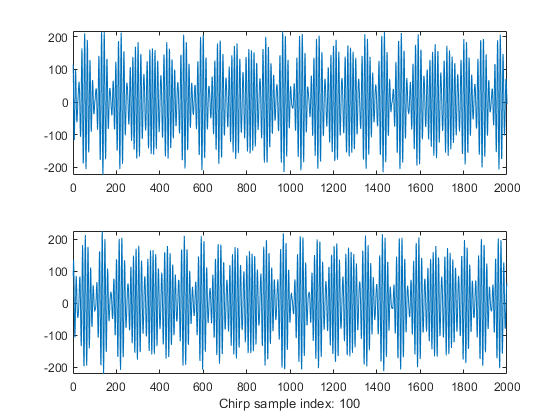

chirp_sample_idx = 100; % randi(ChirpNum);
% figure; 
% subplot(2,1,1);plot(RX0_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,1,2);plot(RX0_CHIRPS_Q(chirp_sample_idx,:))
% xlabel(['Chirp sample index: ',num2str(chirp_sample_idx)])

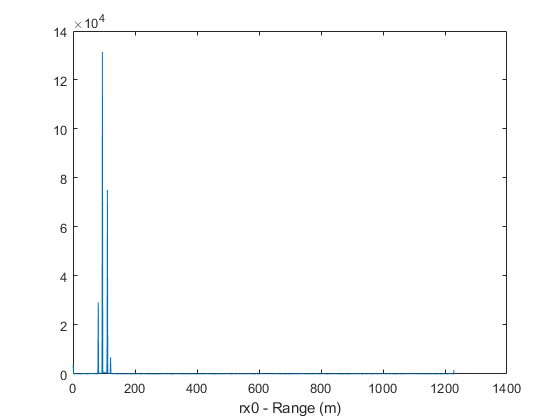

sample_chirp_data = double(squeeze(RX0_CHIRPS_I(chirp_sample_idx,:))) ...
    + 1j*double(squeeze(RX0_CHIRPS_Q(chirp_sample_idx,:)));
sample_chirp_data(2048) = 0;
f = abs(fft(sample_chirp_data.*hamming(2048)'));
xlab = 1:2048;
xlab = xlab*Dres;
figure; plot(xlab,f);xlabel('rx0 - Range (m)')

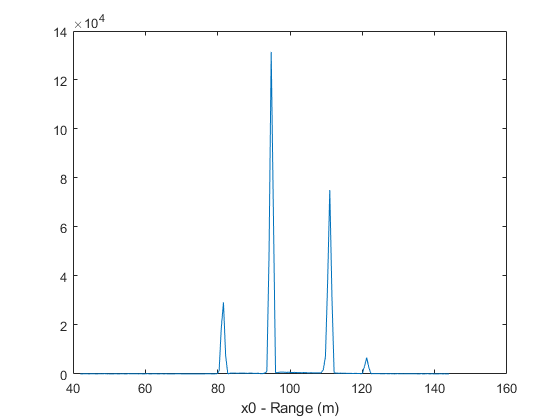

% figure; plot(xlab(70:240),f(70:240));xlabel('x0 - Range (m)')

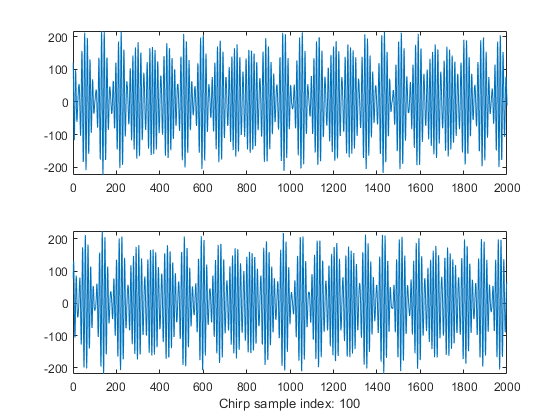

% chirp_sample_idx = 100; % randi(ChirpNum);
% figure; 
% subplot(2,1,1);plot(RX1_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,1,2);plot(RX1_CHIRPS_Q(chirp_sample_idx,:))
% xlabel(['Chirp sample index: ',num2str(chirp_sample_idx)])

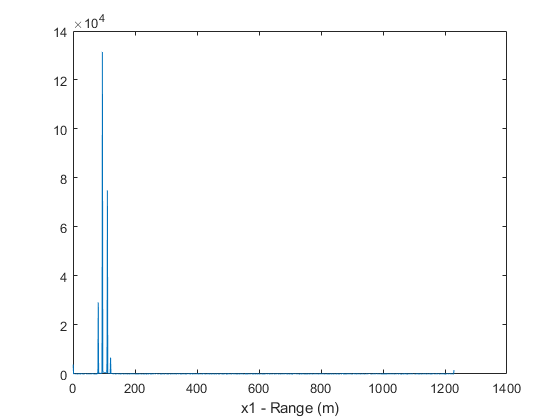

% sample_chirp_data = double(squeeze(RX1_CHIRPS_I(chirp_sample_idx,:))) ...
%     + 1j*double(squeeze(RX1_CHIRPS_Q(chirp_sample_idx,:)));
% sample_chirp_data(2048) = 0;
% f = abs(fft(sample_chirp_data.*hamming(2048)'));
% xlab = 1:2048;
% xlab = xlab*Dres;
% figure; plot(xlab,f);xlabel('x1 - Range (m)')

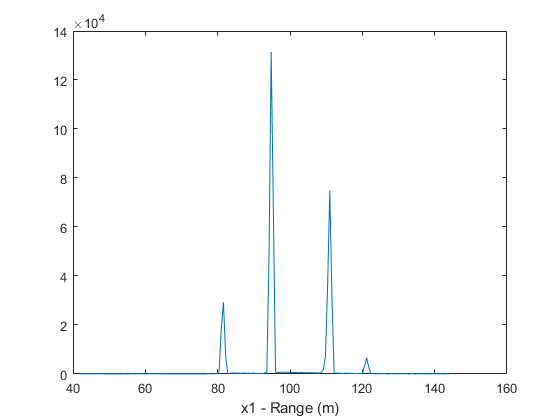

% figure; plot(xlab(70:240),f(70:240));xlabel('x1 - Range (m)')

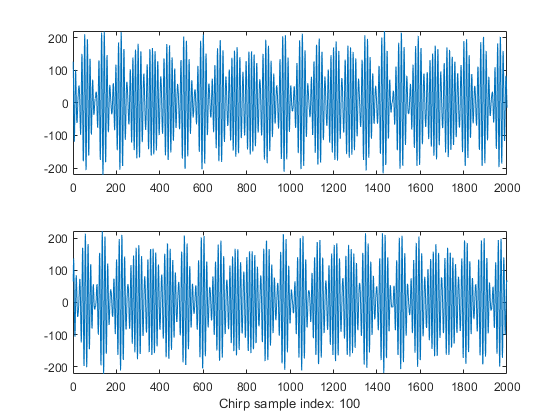

% chirp_sample_idx = 100; % randi(ChirpNum);
% figure; 
% subplot(2,1,1);plot(RX2_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,1,2);plot(RX2_CHIRPS_Q(chirp_sample_idx,:))
% xlabel(['Chirp sample index: ',num2str(chirp_sample_idx)])

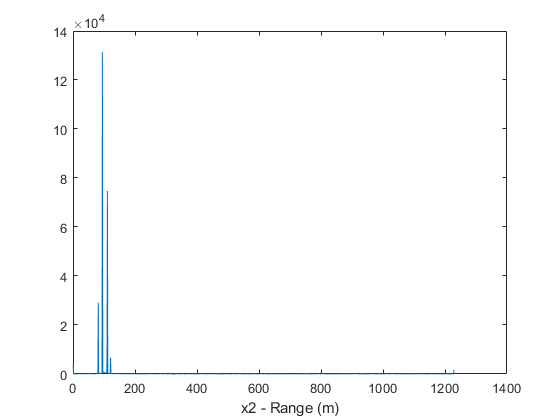

% sample_chirp_data = double(squeeze(RX2_CHIRPS_I(chirp_sample_idx,:))) ...
%     + 1j*double(squeeze(RX2_CHIRPS_Q(chirp_sample_idx,:)));
% sample_chirp_data(2048) = 0;
% f = abs(fft(sample_chirp_data.*hamming(2048)'));
% xlab = 1:2048;
% xlab = xlab*Dres;
% figure; plot(xlab,f);xlabel('x2 - Range (m)')

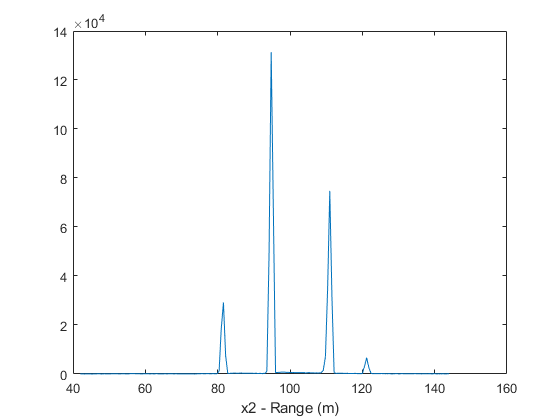

% figure; plot(xlab(70:240),f(70:240));xlabel('x2 - Range (m)')

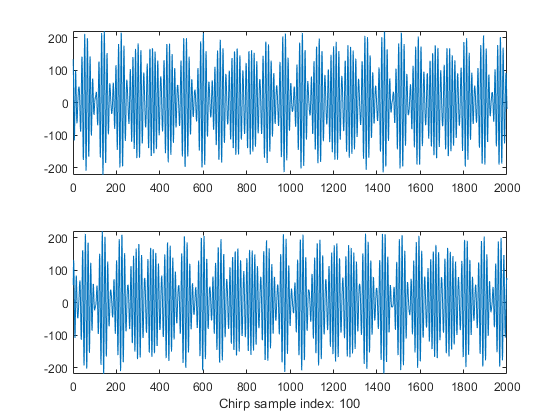

% chirp_sample_idx = 100; % randi(ChirpNum);
% figure; 
% subplot(2,1,1);plot(RX3_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,1,2);plot(RX3_CHIRPS_Q(chirp_sample_idx,:))
% xlabel(['Chirp sample index: ',num2str(chirp_sample_idx)])

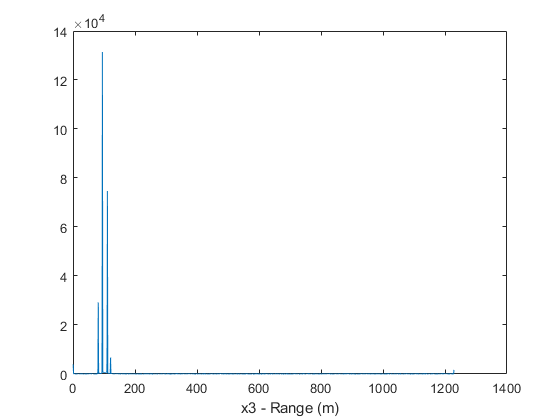

% sample_chirp_data = double(squeeze(RX3_CHIRPS_I(chirp_sample_idx,:))) ...
%     + 1j*double(squeeze(RX3_CHIRPS_Q(chirp_sample_idx,:)));
% sample_chirp_data(2048) = 0;
% f = abs(fft(sample_chirp_data.*hamming(2048)'));
% xlab = 1:2048;
% xlab = xlab*Dres;
% figure; plot(xlab,f);xlabel('x3 - Range (m)')

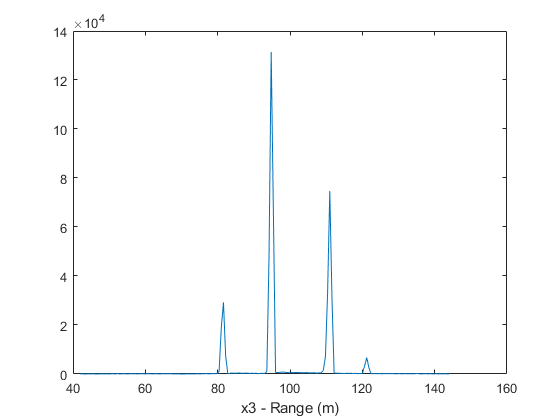

% figure; plot(xlab(70:240),f(70:240));xlabel('x3 - Range (m)')

% disp("---------------------------------------------------")

---------------------------------------------------


% disp(" FMCW Radar Simulation Outputs are:                ")

 FMCW Radar Simulation Outputs are:                


% disp("       RX0_CHIRPS_I                                ")

       RX0_CHIRPS_I                                


% disp("       RX0_CHIRPS_Q                                ")

       RX0_CHIRPS_Q                                


% disp("       RX1_CHIRPS_I                                ")

       RX1_CHIRPS_I                                


% disp("       RX1_CHIRPS_Q                                ")

       RX1_CHIRPS_Q                                


% disp("       RX2_CHIRPS_I                                ")

       RX2_CHIRPS_I                                


% disp("       RX2_CHIRPS_Q                                ")

       RX2_CHIRPS_Q                                


% disp("       RX3_CHIRPS_I                                ")

       RX3_CHIRPS_I                                


% disp("       RX3_CHIRPS_Q                                ")

       RX3_CHIRPS_Q                                


% disp("---------------------------------------------------")

---------------------------------------------------
